# DSZOB, cvičenie 4.

## **Zadanie:**

## **Úloha 1 - **Analýza signálu

**Nasnímajte signál zvuku ladičky. **

Vizualizujte nasnímaný signál v priestorovej doméne. Na základe vizualizácie vyberte vhodný úsek, vypočítajte a vizualizujte preň Fourierovu transformáciu:

- Cez funkciu **fft** na malej vzorke dát (napr. 512)

- Prepočítajte index spektrálneho koeficienta na frekvenciu pre najväčsiu hodnotu v grafe

- Cez funkciu **spectrogram**

- Zistite dominantnú frekvenciu daného signálu a vyznačte ju v grafe.

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

fork = audioread("Asignments\Assignment_3\ladicka.wav");
fork_info = audioinfo("Asignments\Assignment_3\ladicka.wav")

fork_info = struct with fields:
             Filename: 'C:\Users\peter\Desktop\FIIT 2013-14\DSOZB\Asignments\Assignment_3\ladicka.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 2
           SampleRate: 44100
         TotalSamples: 346112
             Duration: 7.8483
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


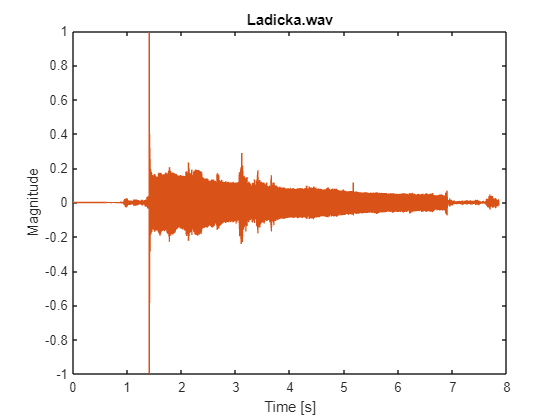

fs = fork_info.SampleRate;
time_axis = 0:1/fs:fork_info.Duration;
time_axis(end) = [];    %Fix for rounding issue
plot(time_axis, fork);
title("Ladicka.wav")
xlabel("Time [s]");
ylabel("Magnitude")

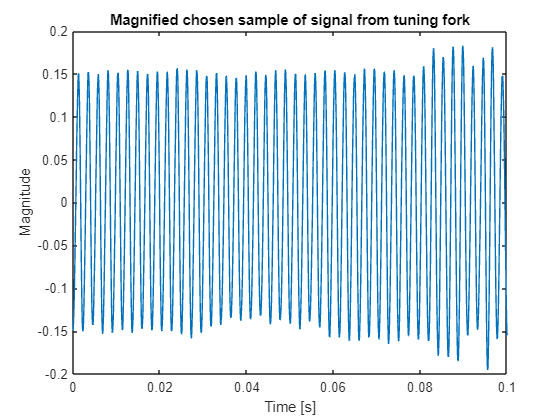

fork_sample = fork(fs*2: fs*4, 1);
time_axis_sample = 0:1/fs:2;
plot(time_axis_sample, fork_sample); % between first and second second
title("Magnified chosen sample of signal from tuning fork")
xlabel("Time [s]");
ylabel("Magnitude");
xlim([0,0.1])

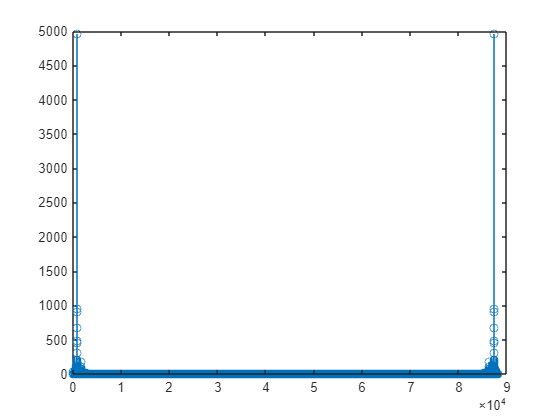

fork_dft = fft(fork_sample);
stem(abs(fork_dft))

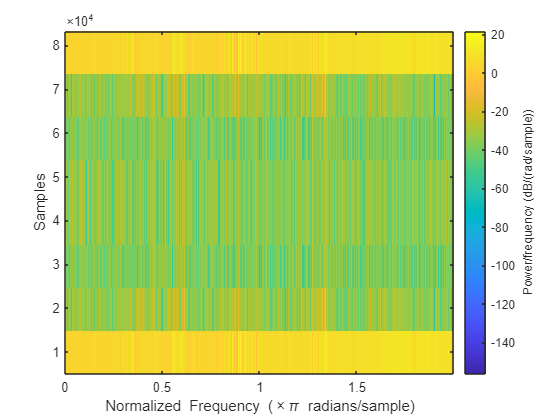

spectrogram(fork_dft)

## **Úloha 2 - Zero Padding v spektrálnej doméne**

Vygenerujte si náhodne zložený signál s dĺžkou 1 sekunda a s voľne zvolenou malou vzorkovacou frekvenciou. Zvolte si parametre signálu tak, aby najväčšia frekvencia generovaného signálu neprekročila 16Hz a vzorkovacia frekvencia pod 64Hz. Dbajte pri tom na to, aby bol splnený Nyquistov teorém. 

Vykonajte zero padding signálu v spektrálnej doméne tak, že doplníte nulami spektrum od jeho stredu (stred symetrie musí ostať zachovaný). Doplnenie vykonajte na velkosť vzorky 1024. Následne vykonajte spätnú transformáciu do časovej domény. Pôvodný signál, ako aj novo vytvorený spoločne vizualizujte v jednom grafe, kde x-os bude reprezentovať čas v rozsahu 1 sek.

Zodpovedajte nasledovné otázky:

- Akú výhodu nam priniesol zero padding v spektre?

- Vie nám zero padding v spektre pomôcť v prípade, ak bol porušený Nyquistov teorém v pôvodnom signále? (áno/nie)

## Pomôcky:

- complex()

- zeros()

- ifft()

## Poznámka:

- Spektrum signálu obsahuje magnitúdovú aj fázovú zložku. Pri dopĺňaní spektra nulami teda pracujeme s komplexnými číslami (0 + 0*i)

- Po spätnom prepočte inverznej transformacie prenásobte výsledný signál konštantou 1024/Fs pre normalizáciu hodnôt na veľkosť okienka

## **Riešenie:**